# Adding paths


addpath(genpath('SEREEGA-master\')) 
addpath('W:\PhD\MatlabPlugins\fieldtrip-20210906'); % path to fieldtrip
warning('off','all')
global ft_default
ft_default.showcallinfo = 'no';

## Config vars

N_locations = 10; % number of potential source generators
location_distance = 50; % minimum disrtance between generators mm
n_components = [1:10]; % number of components
component_widths = [25:200]; % potential comonent widths in ms
max_amplitude = 1; 
component_range = [200:800]; % componet range within signal
SNR = 0.2; % Signal to noise ratio
fs = 1000; % sample rate
sig_len = 1000; % signal length in ms


## Get leadfield head model and plot

lf = lf_generate_fromnyhead('montage', 'S64');

readlocs(): 'polhemus' format assumed from file extension
readlocs(): Could not read Polhemus coords. Trying to read BESA .elp file.
readlocs(): 'besa' format assumed from file extension
BESA header detected, skipping three lines...
Readlocs: BESA spherical coords. converted, now deleting BESA fields
          to avoid confusion (these fields can be exported, though)


plot_headmodel(lf);

Current plot held


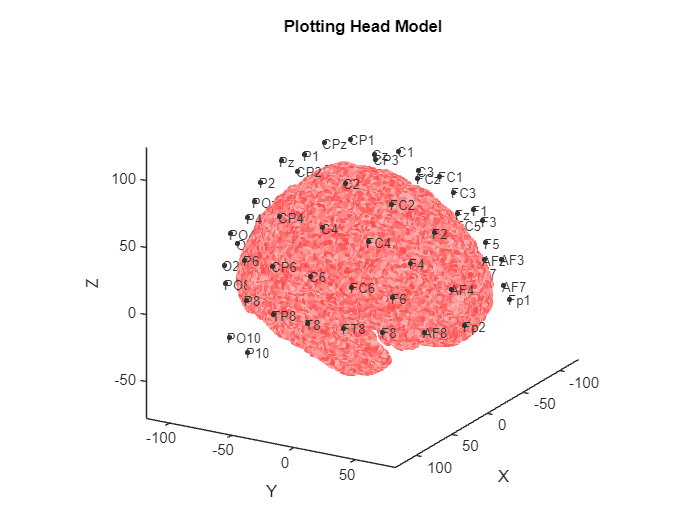

title("Plotting Head Model")

## Get source locations

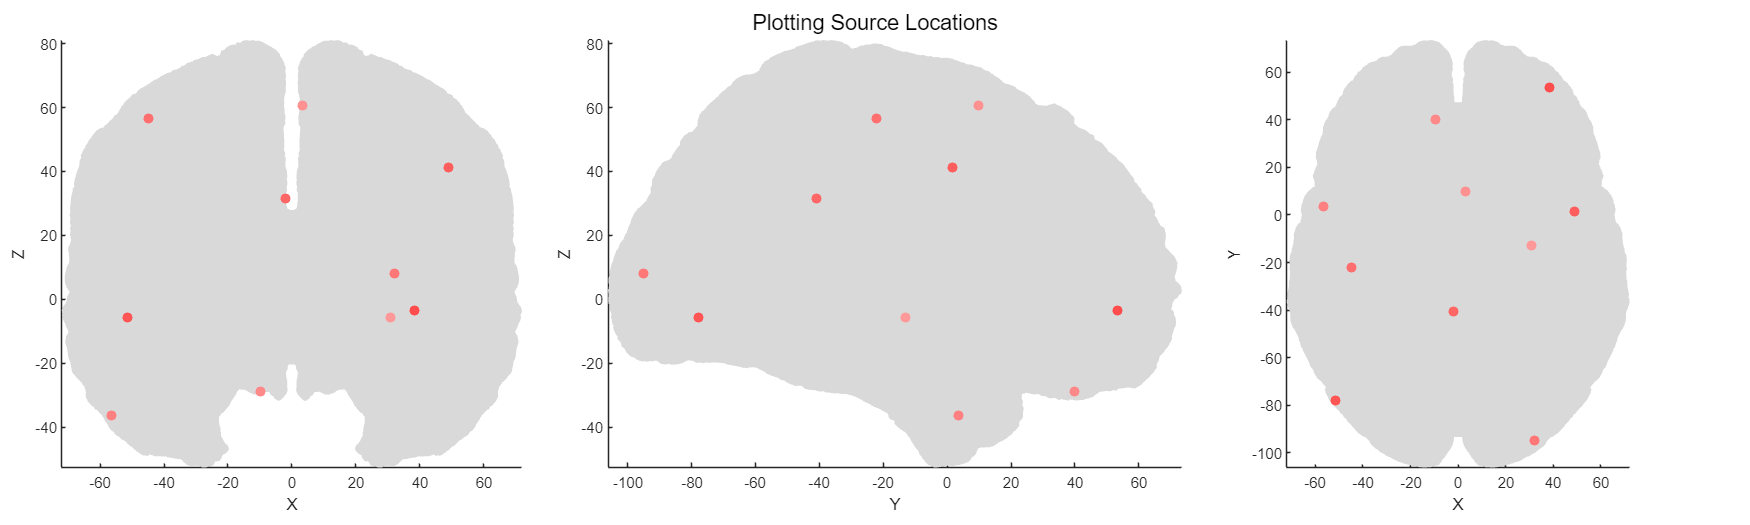

sourcelocs  = lf_get_source_spaced(lf, N_locations, location_distance);
plot_source_location(sourcelocs, lf);
sgtitle("Plotting Source Locations")

## Plot Source projection

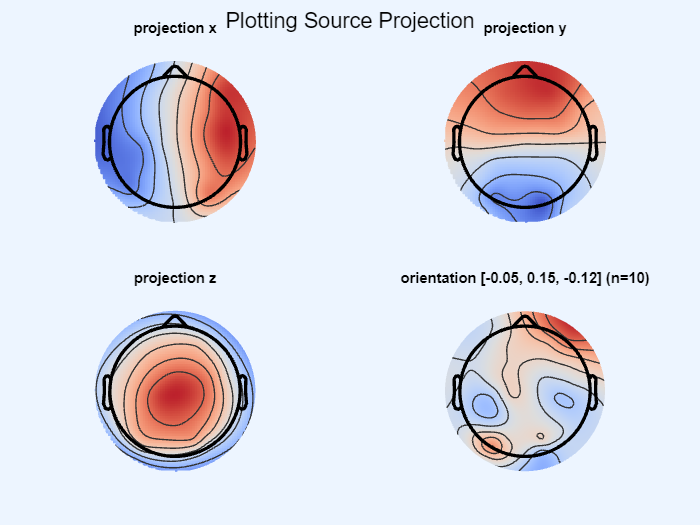

plot_source_projection(sourcelocs, lf);
sgtitle("Plotting Source Projection")

## ERP & noise parameters

amps = [min_amplitude:.1:min_amplitude/2, max_amplitude/2:.1:max_amplitude];
erp = erp_get_class_random(n_component, component_range, component_widths, amps);

noise = struct( ...
                 'type', 'noise', ...
                 'color', 'pink', ...
                 'amplitude', max(abs(min_amplitude),abs(max_amplitude))*SNR);
noise = utl_check_class(noise);
epochs = struct();
epochs.n = 1;             % the number of epochs to simulate
epochs.srate = fs;        % their sampling rate in Hz
epochs.length = sig_len;       % their length in ms

                    % combining into components
c = struct();
c.source = sourcelocs;      % obtained from the lead field, as above
c.signal = {erp,noise};       % ERP class, defined above

## Plotting ERP shape w/o noise

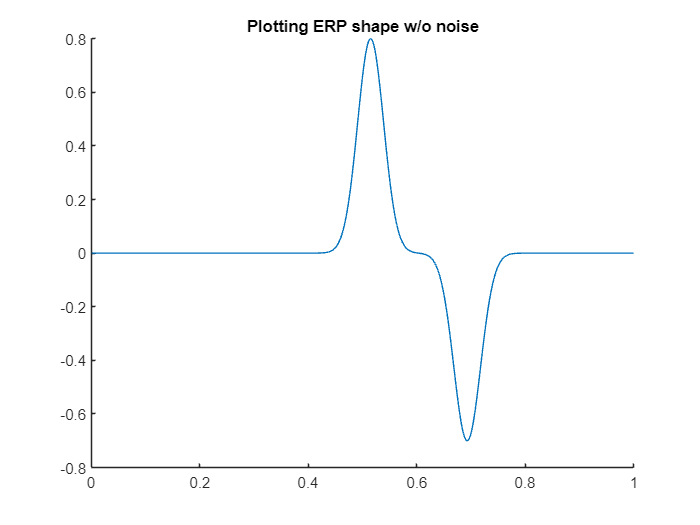

plot_signal_fromclass(erp, epochs);
title("Plotting ERP shape w/o noise")

## Plotting whole ERP Volume

c = utl_check_component(c, lf);
scalpdata = generate_scalpdata(c, lf, epochs);

Generating scalp data... 100.00%
      Remaining: 00:00:00
          Total: 00:00:00
Expected Finish: 12:06:12PM  14-Feb-2024                                                           


EEG = utl_create_eeglabdataset(scalpdata, epochs, lf);
data = eeglab2fieldtrip(EEG, 'timelock', 'none');

cfg = [];
figure; 
ft_multiplotER(cfg,data);

creating layout from data.elec
creating layout for eeg1010 system


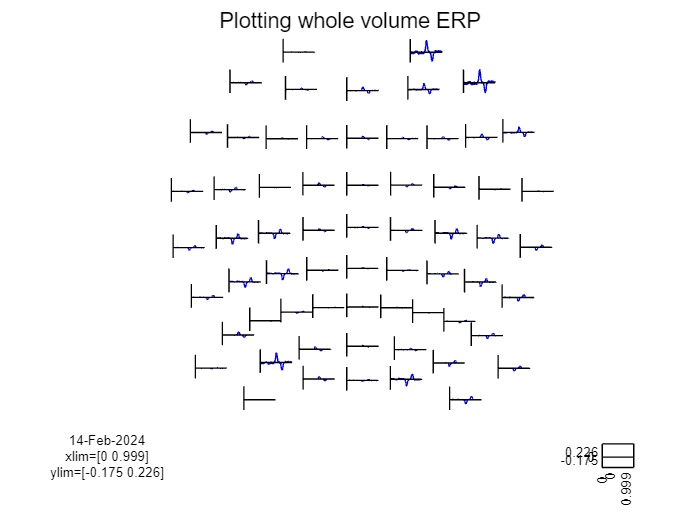

sgtitle("Plotting whole volume ERP")

## Plotting Topomaps through time

cfg = [];
time = data.time;
n_plots = 6;
time_split = round(length(time)/n_plots);
new_time = []


new_time =

     []



for i = 1:n_plots
    start_idx = (i - 1) * time_split + 1;
    end_idx = min(i * time_split, length(time));
    new_time{i} = time(start_idx:end_idx);
end
figure('Position', [100, 100, 1000, 300]);
% Create and display 8 plots
for i = 1:n_plots
    cfg = [];
    cfg.figure = 'gcf';
    cfg.comment = 'no';
    cfg.xlim = [new_time{i}(1), new_time{i}(end)];
    subplot(1, n_plots, i); % Arrange the plots in a 2x4 grid
    ft_topoplotTFR(cfg, data);
    title('')
end

creating layout from data.elec
creating layout for eeg1010 system


creating layout from data.elec
creating layout for eeg1010 system


creating layout from data.elec
creating layout for eeg1010 system


creating layout from data.elec
creating layout for eeg1010 system


creating layout from data.elec
creating layout for eeg1010 system


creating layout from data.elec
creating layout for eeg1010 system


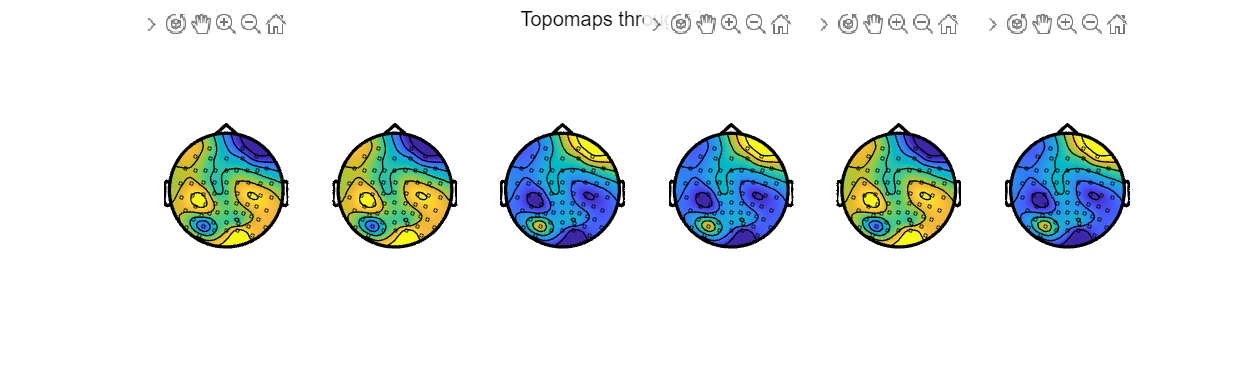


sgtitle('Topomaps through time')